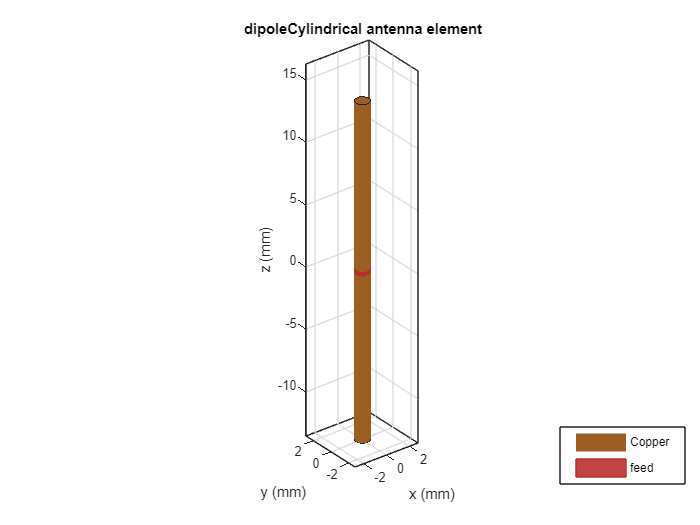

%% Antenna Properties 

RA = design(dipoleCylindrical, 5000*1e6);
RA.Length = 0.0271;
RA.Conductor.Name = 'Copper';
RA.Conductor.Conductivity = 5.96*1e7;
RA.Conductor.Thickness = 3.556e-05;
% Show

show(RA); 

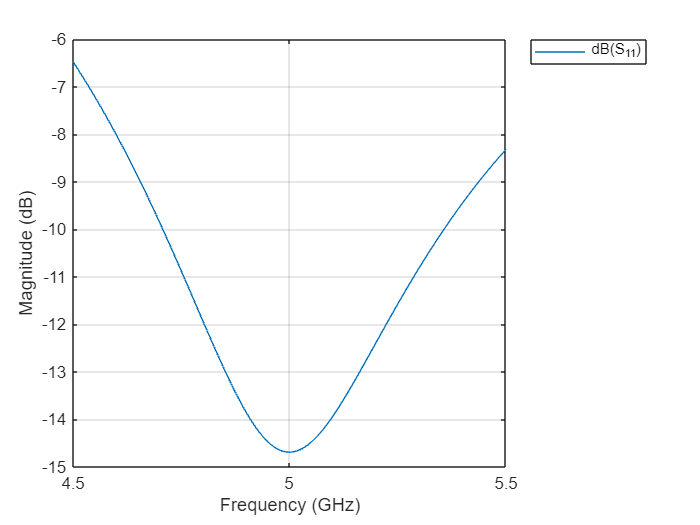


%% Antenna Analysis 
% Define plot frequency 
plotFrequency = 5000*1e6;
% Define frequency range 
freqRange = (4500:5:5500)*1e6;
% Reference Impedance 
refImpedance = 50;
% sparameter
s = sparameters(RA, freqRange, refImpedance); 
rfplot(s);% pattern

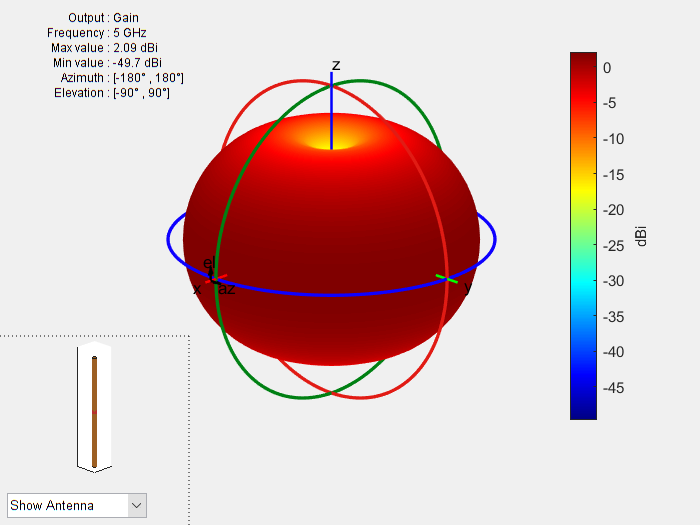

pattern(RA, plotFrequency);% azimuth

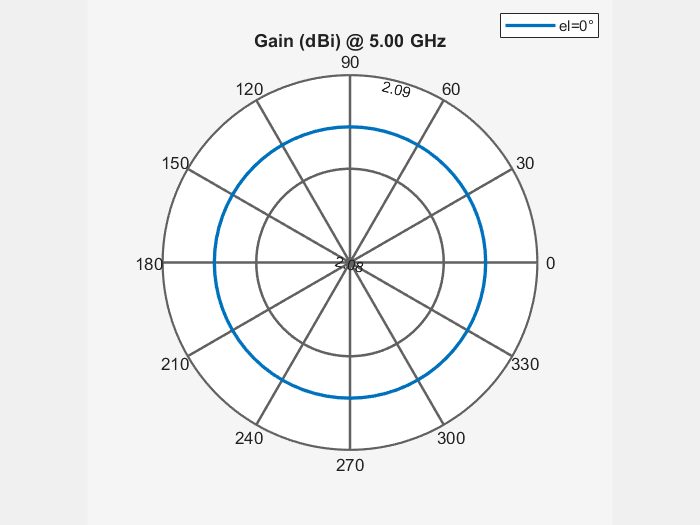

patternAzimuth(RA, plotFrequency, 0, 'Azimuth', 0:5:360);% elevation

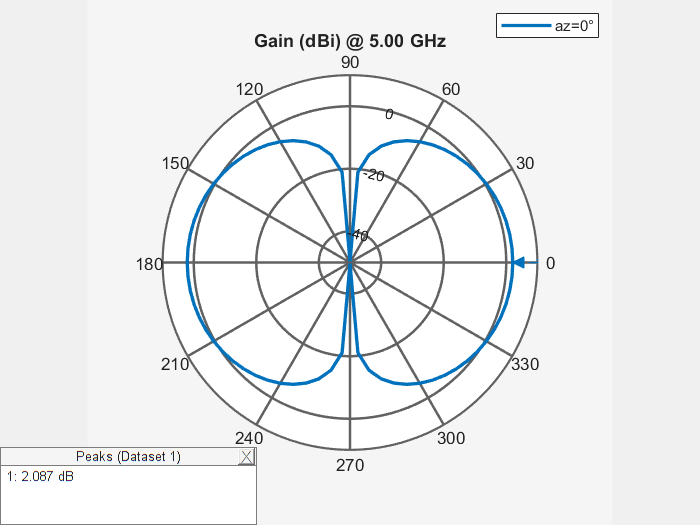

patternElevation(RA, plotFrequency,0,'Elevation',0:5:360);% current

current(RA, plotFrequency);